**EE 150**

**Signals and Systems**

** Lab 4 Fourier Transform**

Date Performed: 

Class Id: Lab4_Thur_105_

Name & ID: 王鹏豪 2021533138 周守琛 2021533042

Lab4_Thur_105_王鹏豪_2021533138_周守琛_2021533042

1. $h\left(t\right)=u\left(t\right)-u\left(t-2\right),x\left(t\right)=e^{-3t} u\left(t\right)$. $H\left(j\omega \right)$and $X\left(j\omega \right)$ are the fouriertransform of $h{\left(t\right)}$ and $x{\left(t\right)}$.

a. Draw $h{\left(t\right)}*x{\left(t\right)}$ and  the inverse fourier transform of $H\left(j\omega \right)\cdot X\left(j\omega \right)$ in a 2*1 subplot. ($*$ means convolution and $\cdot$ means multiplication)

b. What do you find by comparing the result you get in a? (Which property of the Fourier transform does it fit?)

clear;
clf;

a.

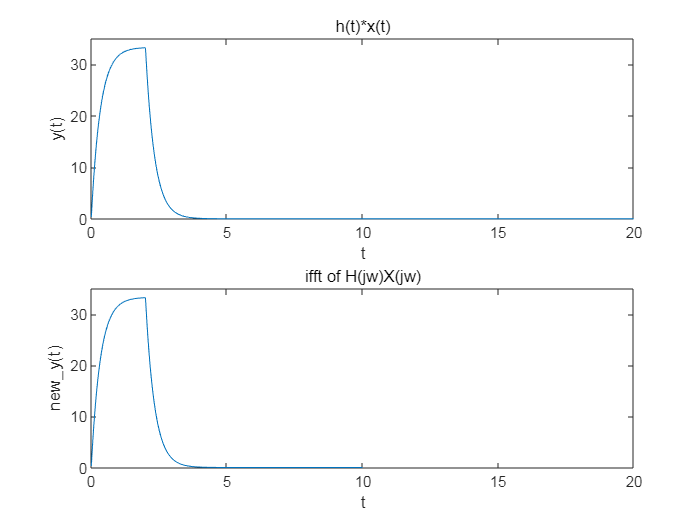

dt = 0.01;
t = 0:dt:10;
new_t = 0:dt:20;
h = heaviside(t) - heaviside(t-2);
x = exp(-3*t) .* heaviside(t);

y = conv(h, x);
subplot(2,1,1);
plot(new_t,y);
title("h(t)*x(t)");
xlabel("t");
ylabel("y(t)");
axis([0 20 0 35]);

H = fft(h);
X = fft(x);
Y = H .* X;
new_y = ifft(Y);

subplot(2,1,2);
plot(t,new_y);
title("ifft of H(jw)X(jw)");
xlabel("t");
ylabel("new\_y(t)");
axis([0 20 0 35]);

b.

let the fourier transform of x(t) and h(t) be X(jw),H(jw)

then the fourier transform of x(t)*h(t) is X(jw)H(jw).

2. Import **Lab4_signal4.mat **with function **load()**, then analyze the signal with with function **fft()**. The sampling frequency Fs=1000 (dt=1/Fs). The useful part of the signal is periodic.

Draw the signal and its unilateral amplitude spectrum of the signal in a 2*1 subplot.

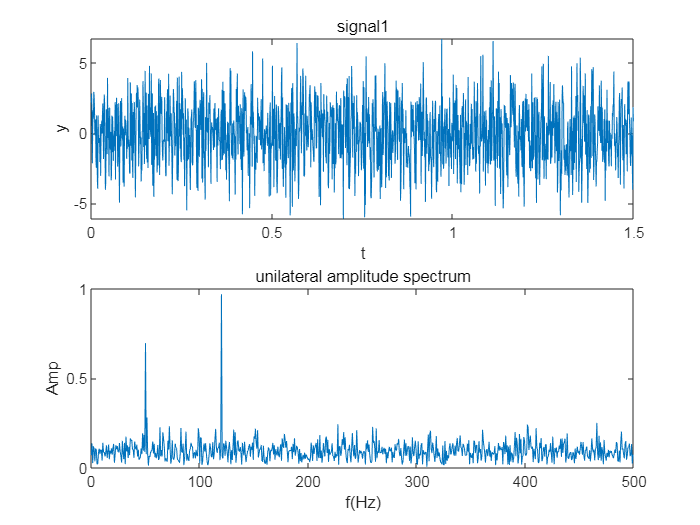

clear;
clf;
load("C:\Users\Administrator\Desktop\MATLAB\Lab4_signal4.mat");

Fs = 1000;
dt = 1/Fs;
N = 1500;
df = Fs/N;

t = (0:N-1)*dt;
X = fft(signal1);
subplot(2,1,1);
plot(t,signal1);
title("signal1");
xlabel("t");
ylabel("y");

f = [0:N-1]*df;
f = f(1:N/2);
X = abs(X)/N;
X = [X(1),2*X(2:N/2)];
subplot(2,1,2);
plot(f,X);
title("unilateral amplitude spectrum")
xlabel("f(Hz)");
ylabel("Amp");

3. Use the Fourier linear property to find the Fourier transform of the following signal. Use both function **fft** and **matrix** method. 

 Draw the real part of the two result in one figure with different line style.

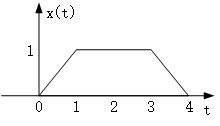

Tips: 

In time domain, x(t) can be expressed as the subtraction of two rectangles. In frequency domain, what is the corresponding operation?

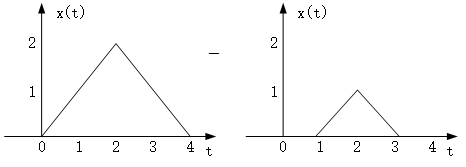

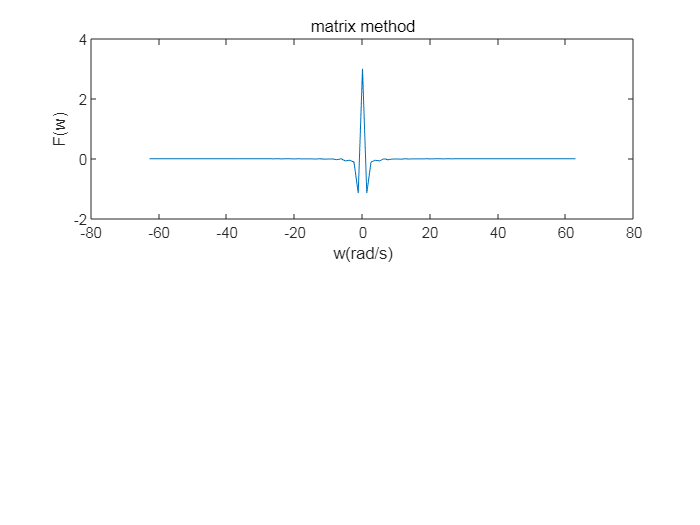

clear;
clf;

dt = 0.00005;
Fs = 1/dt;

t = 0:dt:4;
x1 = 2*tripuls(t-2,4);
x2 = tripuls(t-2,2);
x = x1-x2;

N = length(t);
df = Fs/N;

F1 = fft(x,N);
F = real(F1)*dt;
F = fftshift(F);
w = (-N/2:N/2-1)*df*2*pi;
plot(w,F); hold on;
title("fft method");
xlabel("f(Hz)");
ylabel("Amp");
axis([-80 80 -2 4])



f = x;
M = 50;
k = -M:M;
W = 2*pi*10;
dw = W/M;
Wk = k*dw;
F = f*exp(-1j*t'*Wk)*dt;
F = real(F);

plot(Wk,F);
xlabel("w(rad/s)");
ylabel("F(w)");
title("matrix method");

4. Analysis the signal **LAB4_DTMF4.wav**. Try to find out the DTMF number. 

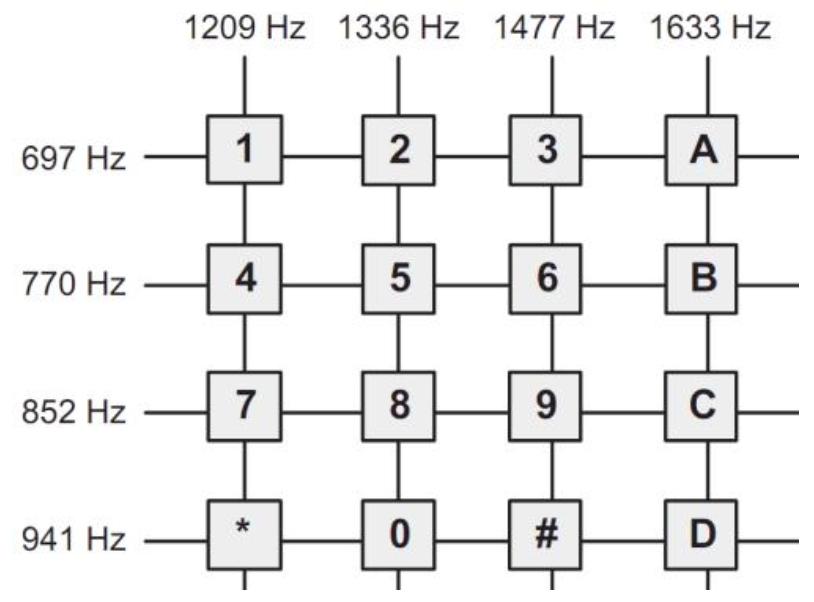

a. Draw the necessary information to analyze the signal. 

b. The number is  _ _ _.

Tips: import **LAB4_DTMF4.wav **with function **[y,Fs]=audioread('filename').**

clear;
clf;
[y,Fs]=audioread("C:\Users\Administrator\Desktop\MATLAB\LAB4_DTMF4.wav");

a.

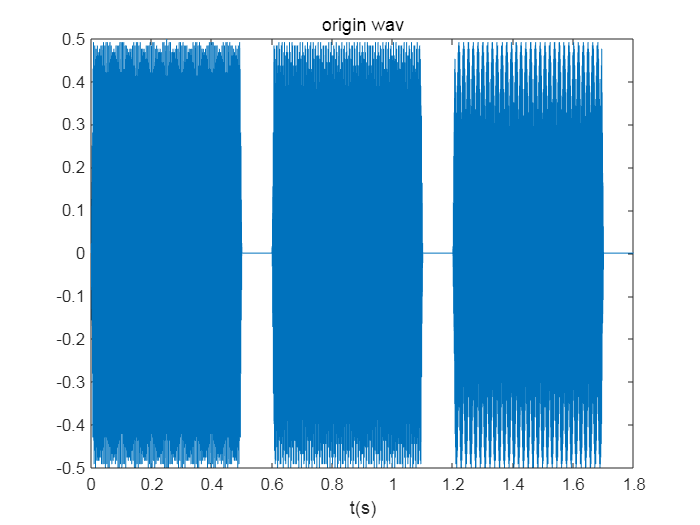

N = length(y);
t = (0:N-1)/Fs;
figure(1);
%sound(y,Fs);
plot(t,y);
title("origin wav");
xlabel("t(s)");

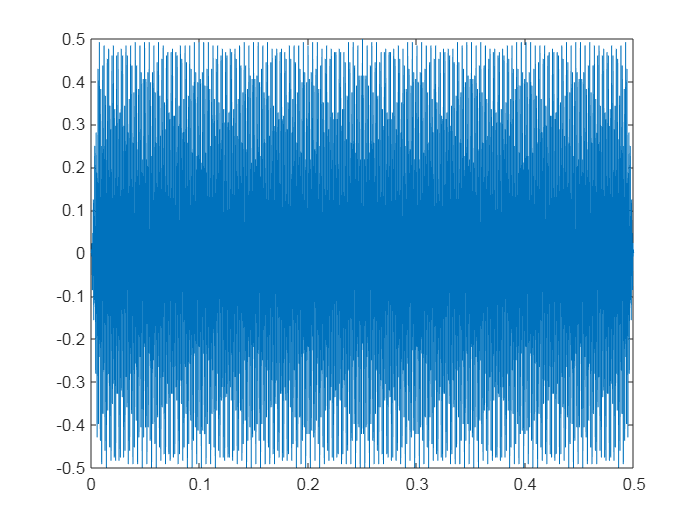

dt = 1/Fs;

y1 = y(1:0.5*Fs);
t1 = 0:dt:0.5-dt;
figure(2);
plot(t1,y1);

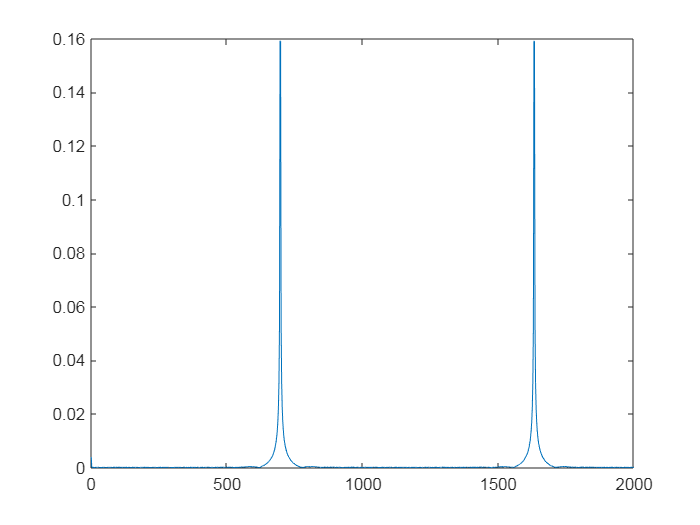


figure(3);
N = length(y1);
df = Fs/N;
f = [0:N-1]*df;
f = f(1:N/2);
X = (abs(fft(y1))/N)';
X = [X(1),2*X(2:N/2)];
plot(f,X);
xlim([0,2000]);

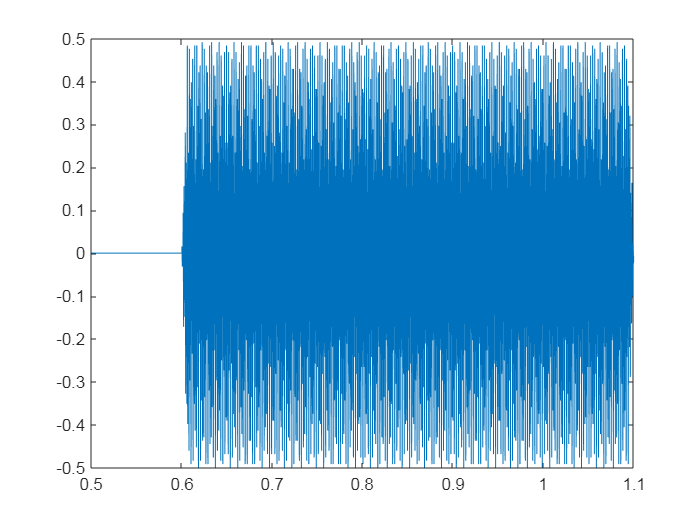


y2 = y(0.5*Fs:1.1*Fs-1);
t2 = 0.5:dt:1.1-dt;
figure(4);
plot(t2,y2);

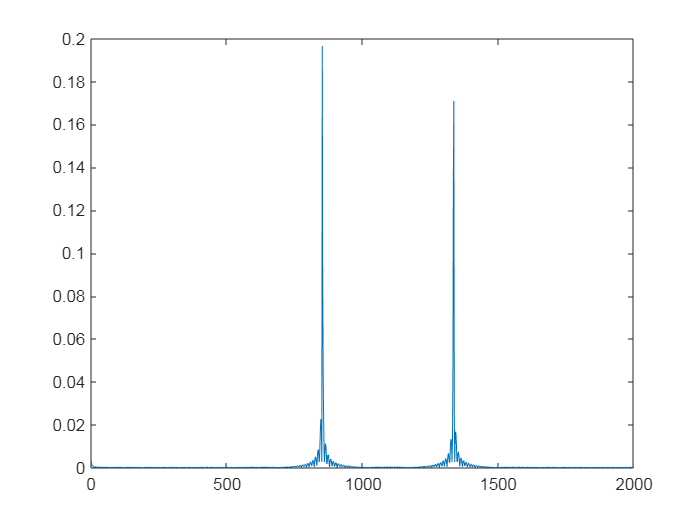

figure(5);
N = length(y2);
df = Fs/N;
f = [0:N-1]*df;
f = f(1:N/2);
X = (abs(fft(y2))/N)';
X = [X(1),2*X(2:N/2)];
plot(f,X);
xlim([0,2000]);

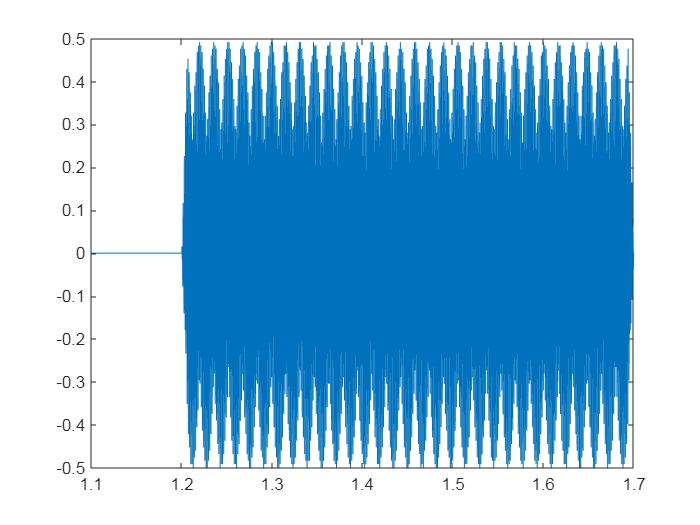



y3 = y(1.1*Fs:1.7*Fs-1);
t3 = 1.1:dt:1.7-dt;
figure(6);
plot(t3,y3);

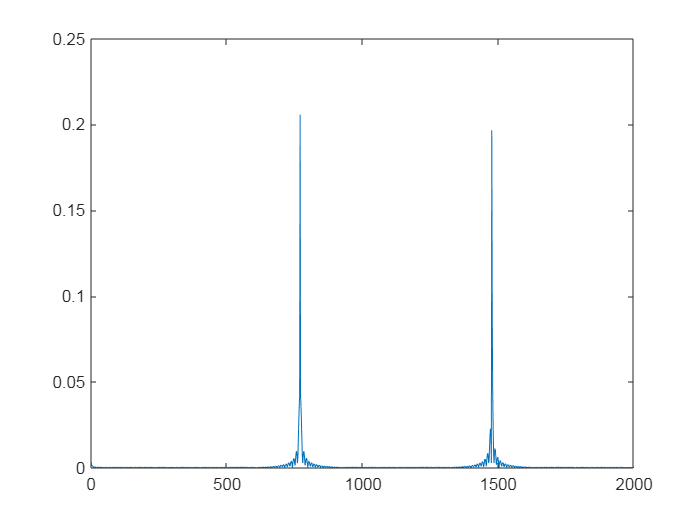


figure(7);
N = length(y3);
df = Fs/N;
f = [0:N-1]*df;
f = f(1:N/2);
X = (abs(fft(y3))/N)';
X = [X(1),2*X(2:N/2)];
plot(f,X);
xlim([0,2000]);

b.

the number is A 8 6

5.  Typically, humans can make sounds in the range of 100Hz to 10kHz and can hear sounds in the range of 20Hz to 20kHz. In *Lab4_voice.mat*, there is a voice signal submerged in the noise. **Load *****Lab4_voice_4.mat****.* Process the signal and try to find out what he/she said. (No filter is needed.)

a. Finish your code with proper explanation for the key code.

b. Plot the time domain and frequency domain diagrams of the signal before and after processing in a 2x2 subplot.

c. Play and listen to the voice signal before and after the processing. What did he/she say?

clear;
clf;

a.b.

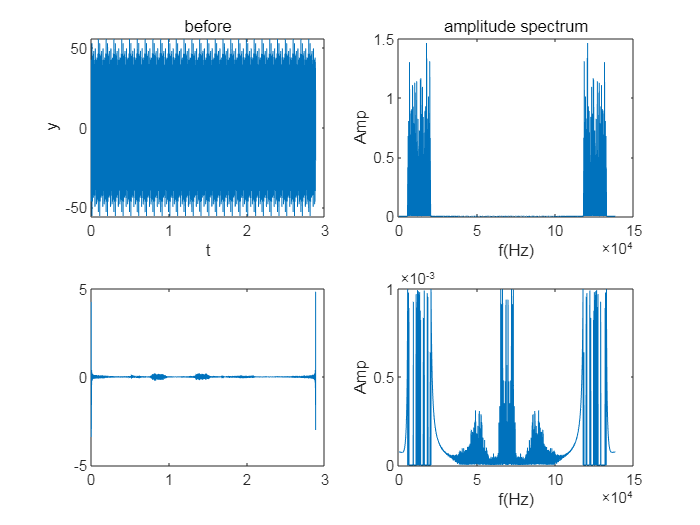

load("C:\Users\Administrator\Desktop\MATLAB\Lab4_voice_4.mat");
N = length(pollutedVol);
t = (0:N-1)/Fs;
%sound(pollutedVol,Fs);

dt = 1/Fs;
df = Fs/N;

subplot(2,2,1);
plot(t,pollutedVol);
title("before");
xlabel("t");
ylabel("y");

subplot(2,2,2);
X = fft(pollutedVol);
X = fftshift(X);
x_amp = abs(X)/N;
plot(x_amp);
title("amplitude spectrum")
xlabel("f(Hz)");
ylabel("Amp");


for i=(1:N)
    pos = i;
    %if(i>N/2)
    %    pos = N - i;
    %end
    %if(pos<=100)
    %    X(i)=0;
    %end
    %if(pos>=10000)
    %    X(i)=0;
    %end
    if(x_amp(i)>0.001)
        X(i)=0;
    end
end

X = ifftshift(X);
after = ifft(X);
subplot(2,2,3);
plot(t,after);
X = fft(after);
X = fftshift(X);
x_amp = abs(X)/N;
subplot(2,2,4);
plot(x_amp);
%title("unilateral amplitude spectrum")
xlabel("f(Hz)");
ylabel("Amp");

c. she said "恭喜发财".

sound(after,Fs);